# Worksheet 4

In this worksheet, we switch to differential equations for functions with more than one independent variable, for example functions depending on several space dimensions.

Such differential equations are called partial differential equations. We start with a first simple example, the two-dimensional stationary heat equation

$T_{xx} + T_{yy} = -2\pi^2 \sin(\pi x) \sin(\pi y)$    (1)

on the unit square $\Omega =]0, 1[^2$ with the temperature $T (x, y)$, the two-dimensional coordinates $x$ and $y$, and homogeneous Dirichlet boundary conditions

$T (x, y) = 0 \quad \forall (x, y) \in \partial \Omega$.    (2)

The boundary value problem (1),(2) has the analytical solution

$T (x, y) = \sin(\pi x) \sin(\pi y)$.    (3)

**a)** The discretization of (1) and (2) leads to a large system of linear equations for the values $T_{i,j}$ , $i \in \{1, \dots , N_x \}$, $j \in \{1, \dots , N_y\}$ denoting the approximate values of the temperature $T$ at the discrete grid points $\left( i \cdot \frac{1}{N_x+1} , j \cdot \frac{1}{N_y+1}\right)$ .

Use the finite difference approximation of the second derivatives

$T_{xx} |_{i,j} \approx \frac {T_{i-1,j} - 2T_{i,j} + T_{i+1,j}}{h^2_x}$ ,


$$T_{yy} |_{i,j} \approx \frac {T_{i,j-1} - 2T_{i,j} + T_{i,j+1}}{h^2_y}$$


with $h_x = \frac{1} {N_x+1}$ and $h_y = \frac{1} {N_y+1}$ .

Sketch a few lines of the resulting system in the following scheme

[...]

**b)** Implement a function creating the matrix from **a)** as a function of $N_x$ and $N_y$ .

    `function A = full_matrix(N_x, N_y)`

`        h2_x = (1/(N_x+1))^2;`

`        h2_y = (1/(N_y+1))^2;`

`        d = (-2/h2_x-2/h2_y)*ones(N_x*N_y,1);`

`        c = 1/h2_y*ones(N_x*N_y-1,1);`

`        c (N_x:N_x:end) = 0; % takes into account the jump on the next column`

`        e = 1/h2_x*ones(N_x*N_y-N_x,1);`

`        A = diag(d)...`

`            +diag(c,1)...`

`            +diag(c,-1)...`

`            +diag(e, N_x)...`

`            +diag(e, -N_x);`

`        end`

**c)** Since the matrix created in **b)** is mostly composed of zeros, and only a few entries are nonzero, it is advantageous to directly create a sparse matrix. Thus, implement a different function creating the matrix from **a)** as a function of $N_x$ and $N_y$ in sparse format.

**Remark:** Do NOT(!!!) call `sparse(A)`, as this assumes that you have the full/dense matrix beforehand—and this is exactly what we are trying to avoid.

Instead, use your knowledge on the matrix structure to build it up.

    `function A = sparse_matrix(N_x, N_y)`

`    h2_x = (1/(N_x+1))^2;`

`    h2_y = (1/(N_y+1))^2;`

`    d = (-2/h2_x-2/h2_y)*ones(N_x*N_y,1);`

`    c = 1/h2_y*ones(N_x*N_y-1,1);`

`    c (N_x:N_x:end) = 0; % takes into account the jump on the next column`

`    e = 1/h2_x*ones(N_x*N_y-N_x,1);`

`    x = [1:(N_x*N_y),2:(N_x*N_y),1:(N_x*N_y-1),(N_x+1):(N_x*N_y),1:(N_x*N_y-N_x)];`

`    y = [1:(N_x*N_y),1:(N_x*N_y-1),2:(N_x*N_y),1:(N_x*N_y-N_x),(N_x+1):(N_x*N_y)];`

`    A = sparse(x,y,cat(1,d, c, c, e, e));`

`    end`

**d)** Implement a Gauss-Seidel solver for the system in **a)** as a function of the right hand side $b$, $N_x$ , and $N_y$ . The output of the solver is a matrix with dimensions $N_x$ and $N_y$ containing the computed approximate values of $T$ at the grid points $(i \cdot h_x , j \cdot h_y )$ in entry $(i, j)$. As a termination criterion for the iteration use an accuracy limit of $10^{-4}$ for the residual norm.

**Remark 1:** Do NOT(!!!) use the explicit system matrices from **b)** or **c)** in your Gauss-Seidel solver. Use your knowledge about the particular, constant form of the lines of the linear system to completely avoid any storage of matrix entries!

**Remark 2:** Think about the how to handle the boundary points for an efficient traversal of the mesh! Also, remember to only return the inner domain values from your Gauss-Seidel implementation!

**Remark 3:** The residual norm for a general system $Ax = b$ is defined as

$R = \sqrt{\frac{1}{N}\sum_k\left(b_k-\sum_m a_{k,m}x_m\right)^2}$,

where $N$ denotes the number of unknowns. In the Gauss-Seidel solver, $N = N_x \cdot N_y$ , $a_{i,j}$ are not stored (but known), and the entries of $x$ are the temperature values $T_{i,j}$ at the grid points $(i \cdot h_x , j \cdot h_y )$.

%% MISSING

**e)** Solve the system $Ax = b$ from **a)**

**1)** storing the system matrix as a “normal” (i.e., full) $N \times N$ matrix and using the MATLAB direct solver,

**2)** storing the system matrix as a sparse matrix and using the MATLAB direct solver,

**3)** without storing the system matrix (use Gauss-Seidel with zero as initial guess for $T$ !).

x_full =     0.0967    0.1367    0.0967
    0.1817    0.2570    0.1817
    0.2448    0.3462    0.2448
    0.2784    0.3937    0.2784
    0.2784    0.3937    0.2784
    0.2448    0.3462    0.2448
    0.1817    0.2570    0.1817
    0.0967    0.1367    0.0967


x_sparse =     0.0967    0.1367    0.0967
    0.1817    0.2570    0.1817
    0.2448    0.3462    0.2448
    0.2784    0.3937    0.2784
    0.2784    0.3937    0.2784
    0.2448    0.3462    0.2448
    0.1817    0.2570    0.1817
    0.0967    0.1367    0.0967


x_GS =     0.0753    0.0867    0.0753
    0.1761    0.2480    0.1761
    0.2434    0.3442    0.2434
    0.2776    0.3925    0.2776
    0.2758    0.3899    0.2758
    0.2331    0.3277    0.2331
    0.1359    0.1554    0.1359
    0.0675    0.0758    0.0675


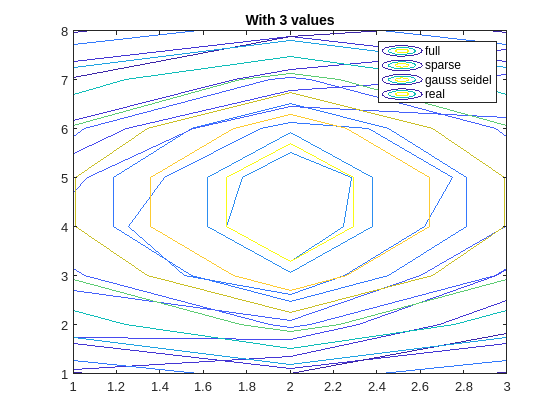

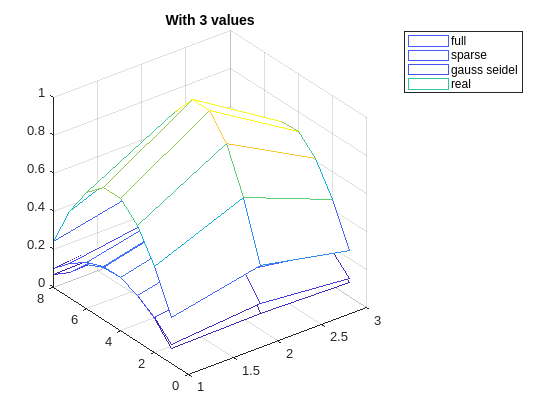

x_full =     0.0614    0.1134    0.1482    0.1604    0.1482    0.1134    0.0614
    0.1192    0.2203    0.2878    0.3115    0.2878    0.2203    0.1192
    0.1701    0.3143    0.4107    0.4445    0.4107    0.3143    0.1701
    0.2111    0.3901    0.5097    0.5516    0.5097    0.3901    0.2111
    0.2398    0.4432    0.5790    0.6267    0.5790    0.4432    0.2398
    0.2546    0.4705    0.6148    0.6654    0.6148    0.4705    0.2546
    0.2546    0.4705    0.6148    0.6654    0.6148    0.4705    0.2546
    0.2398    0.4432    0.5790    0.6267    0.5790    0.4432    0.2398
    0.2111    0.3901    0.5097    0.5516    0.5097    0.3901    0.2111
    0.1701    0.3143    0.4107    0.4445    0.4107    0.3143    0.1701


x_sparse =     0.0614    0.1134    0.1482    0.1604    0.1482    0.1134    0.0614
    0.1192    0.2203    0.2878    0.3115    0.2878    0.2203    0.1192
    0.1701    0.3143    0.4107    0.4445    0.4107    0.3143    0.1701
    0.2111    0.3901    0.5097    0.5516    0.5097    0.3901    0.2111
    0.2398    0.4432    0.5790    0.6267    0.5790    0.4432    0.2398
    0.2546    0.4705    0.6148    0.6654    0.6148    0.4705    0.2546
    0.2546    0.4705    0.6148    0.6654    0.6148    0.4705    0.2546
    0.2398    0.4432    0.5790    0.6267    0.5790    0.4432    0.2398
    0.2111    0.3901    0.5097    0.5516    0.5097    0.3901    0.2111
    0.1701    0.3143    0.4107    0.4445    0.4107    0.3143    0.1701


x_GS =     0.0503    0.0848    0.1340    0.1530    0.1442    0.1113    0.0605
    0.1140    0.2110    0.2798    0.3057    0.2839    0.2179    0.1181
    0.1678    0.3104    0.4065    0.4408    0.4078    0.3124    0.1692
    0.2100    0.3881    0.5073    0.5493    0.5077    0.3887    0.2104
    0.2391    0.4418    0.5773    0.6249    0.5774    0.4419    0.2392
    0.2539    0.4691    0.6129    0.6633    0.6128    0.4690    0.2538
    0.2536    0.4685    0.6120    0.6623    0.6117    0.4681    0.2533
    0.2381    0.4399    0.5744    0.6213    0.5735    0.4385    0.2372
    0.2085    0.3848    0.5020    0.5419    0.4989    0.3804    0.2054
    0.1664    0.3067    0.3987    0.4278    0.3895    0.2915    0.1571


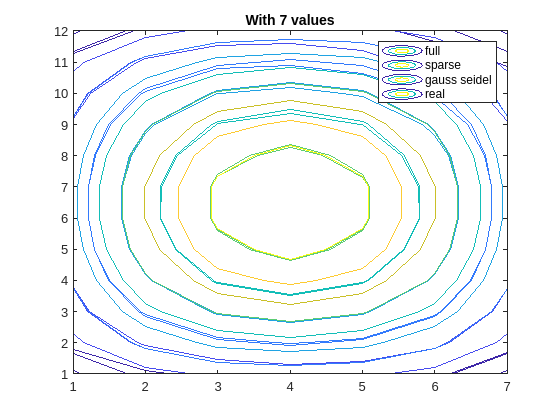

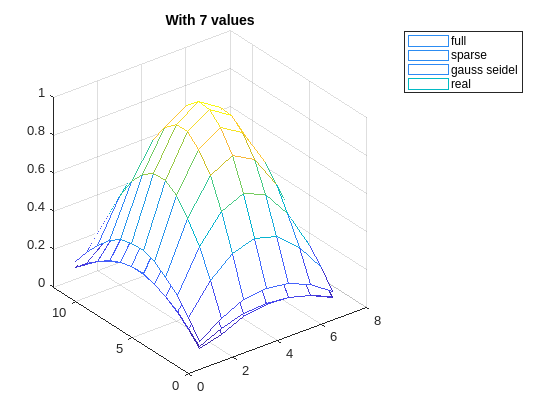

x_full =     0.0253    0.0497    0.0721    0.0918    0.1079    0.1199    0.1273    0.1298    0.1273    0.1199    0.1079    0.0918    0.0721    0.0497    0.0253
    0.0501    0.0982    0.1426    0.1815    0.2134    0.2372    0.2518    0.2567    0.2518    0.2372    0.2134    0.1815    0.1426    0.0982    0.0501
    0.0737    0.1446    0.2099    0.2672    0.3142    0.3491    0.3706    0.3779    0.3706    0.3491    0.3142    0.2672    0.2099    0.1446    0.0737
    0.0957    0.1877    0.2726    0.3469    0.4079    0.4532    0.4812    0.4906    0.4812    0.4532    0.4079    0.3469    0.2726    0.1877    0.0957
    0.1156    0.2267    0.3291    0.4189    0.4925    0.5473    0.5810    0.5923    0.5810    0.5473    0.4925    0.4189    0.3291    0.2267    0.1156
    0.1328    0.2606    0.3783    0.4815    0.5661    0.6290    0.6678    0.6809    0.6678    0.6290    0.5661    0.4815    0.3783    0.2606    0.1328
    0.1471    0.2886    0.4190    0.5333    0.6271    0.6968    0.7397    0.7542    0

x_sparse =     0.0253    0.0497    0.0721    0.0918    0.1079    0.1199    0.1273    0.1298    0.1273    0.1199    0.1079    0.0918    0.0721    0.0497    0.0253
    0.0501    0.0982    0.1426    0.1815    0.2134    0.2372    0.2518    0.2567    0.2518    0.2372    0.2134    0.1815    0.1426    0.0982    0.0501
    0.0737    0.1446    0.2099    0.2672    0.3142    0.3491    0.3706    0.3779    0.3706    0.3491    0.3142    0.2672    0.2099    0.1446    0.0737
    0.0957    0.1877    0.2726    0.3469    0.4079    0.4532    0.4812    0.4906    0.4812    0.4532    0.4079    0.3469    0.2726    0.1877    0.0957
    0.1156    0.2267    0.3291    0.4189    0.4925    0.5473    0.5810    0.5923    0.5810    0.5473    0.4925    0.4189    0.3291    0.2267    0.1156
    0.1328    0.2606    0.3783    0.4815    0.5661    0.6290    0.6678    0.6809    0.6678    0.6290    0.5661    0.4815    0.3783    0.2606    0.1328
    0.1471    0.2886    0.4190    0.5333    0.6271    0.6968    0.7397    0.7542   

x_GS =     0.0218    0.0396    0.0677    0.0897    0.1068    0.1193    0.1269    0.1295    0.1271    0.1198    0.1078    0.0917    0.0721    0.0496    0.0253
    0.0480    0.0945    0.1396    0.1795    0.2121    0.2362    0.2511    0.2562    0.2514    0.2369    0.2132    0.1814    0.1425    0.0982    0.0500
    0.0727    0.1428    0.2081    0.2657    0.3130    0.3482    0.3699    0.3773    0.3702    0.3488    0.3139    0.2670    0.2098    0.1445    0.0737
    0.0952    0.1868    0.2715    0.3458    0.4070    0.4524    0.4805    0.4900    0.4807    0.4529    0.4076    0.3467    0.2724    0.1876    0.0957
    0.1152    0.2261    0.3284    0.4181    0.4918    0.5466    0.5804    0.5918    0.5805    0.5469    0.4922    0.4186    0.3289    0.2266    0.1155
    0.1326    0.2602    0.3778    0.4809    0.5655    0.6285    0.6672    0.6804    0.6673    0.6286    0.5658    0.4812    0.3781    0.2604    0.1328
    0.1470    0.2883    0.4186    0.5328    0.6266    0.6963    0.7392    0.7537    0.7

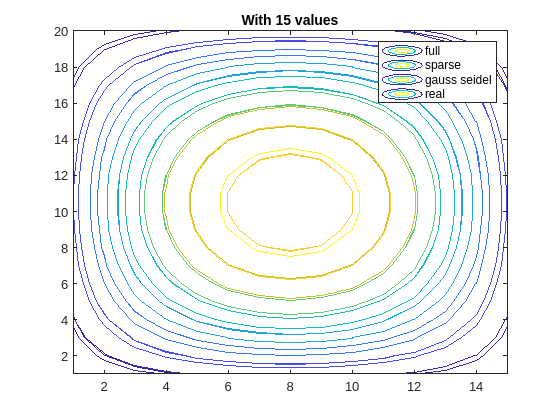

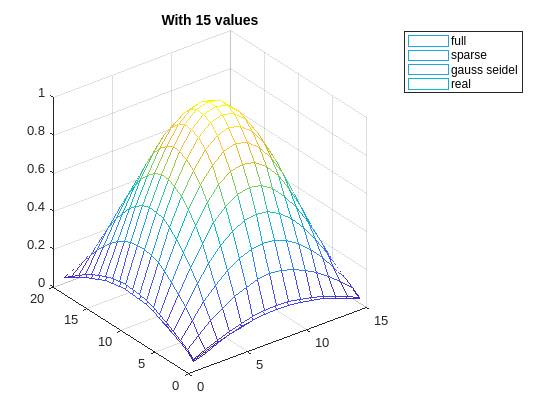

x_full =     0.0080    0.0159    0.0236    0.0312    0.0384    0.0452    0.0516    0.0576    0.0629    0.0677    0.0718    0.0752    0.0779    0.0798    0.0810    0.0814    0.0810    0.0798    0.0779    0.0752    0.0718    0.0677    0.0629    0.0576    0.0516    0.0452    0.0384    0.0312    0.0236    0.0159    0.0080
    0.0159    0.0317    0.0471    0.0621    0.0765    0.0901    0.1029    0.1147    0.1254    0.1349    0.1431    0.1499    0.1553    0.1591    0.1615    0.1622    0.1615    0.1591    0.1553    0.1499    0.1431    0.1349    0.1254    0.1147    0.1029    0.0901    0.0765    0.0621    0.0471    0.0317    0.0159
    0.0237    0.0472    0.0702    0.0926    0.1140    0.1344    0.1535    0.1710    0.1870    0.2011    0.2133    0.2235    0.2315    0.2372    0.2407    0.2419    0.2407    0.2372    0.2315    0.2235    0.2133    0.2011    0.1870    0.1710    0.1535    0.1344    0.1140    0.0926    0.0702    0.0472    0.0237
    0.0313    0.0624    0.0928    0.1224    0.1508    0.17

x_sparse =     0.0080    0.0159    0.0236    0.0312    0.0384    0.0452    0.0516    0.0576    0.0629    0.0677    0.0718    0.0752    0.0779    0.0798    0.0810    0.0814    0.0810    0.0798    0.0779    0.0752    0.0718    0.0677    0.0629    0.0576    0.0516    0.0452    0.0384    0.0312    0.0236    0.0159    0.0080
    0.0159    0.0317    0.0471    0.0621    0.0765    0.0901    0.1029    0.1147    0.1254    0.1349    0.1431    0.1499    0.1553    0.1591    0.1615    0.1622    0.1615    0.1591    0.1553    0.1499    0.1431    0.1349    0.1254    0.1147    0.1029    0.0901    0.0765    0.0621    0.0471    0.0317    0.0159
    0.0237    0.0472    0.0702    0.0926    0.1140    0.1344    0.1535    0.1710    0.1870    0.2011    0.2133    0.2235    0.2315    0.2372    0.2407    0.2419    0.2407    0.2372    0.2315    0.2235    0.2133    0.2011    0.1870    0.1710    0.1535    0.1344    0.1140    0.0926    0.0702    0.0472    0.0237
    0.0313    0.0624    0.0928    0.1224    0.1508    0.

x_GS =     0.0070    0.0130    0.0225    0.0306    0.0381    0.0451    0.0515    0.0575    0.0629    0.0676    0.0718    0.0752    0.0779    0.0798    0.0810    0.0814    0.0810    0.0798    0.0779    0.0752    0.0718    0.0677    0.0629    0.0576    0.0516    0.0452    0.0384    0.0311    0.0236    0.0159    0.0080
    0.0153    0.0305    0.0462    0.0615    0.0761    0.0899    0.1028    0.1146    0.1253    0.1348    0.1430    0.1498    0.1552    0.1591    0.1614    0.1622    0.1614    0.1591    0.1552    0.1498    0.1430    0.1349    0.1254    0.1147    0.1029    0.0901    0.0765    0.0621    0.0471    0.0316    0.0159
    0.0234    0.0466    0.0697    0.0921    0.1137    0.1341    0.1533    0.1709    0.1869    0.2010    0.2132    0.2234    0.2314    0.2372    0.2407    0.2418    0.2407    0.2372    0.2314    0.2234    0.2133    0.2011    0.1869    0.1710    0.1534    0.1344    0.1140    0.0925    0.0702    0.0472    0.0237
    0.0312    0.0621    0.0925    0.1221    0.1505    0.1774

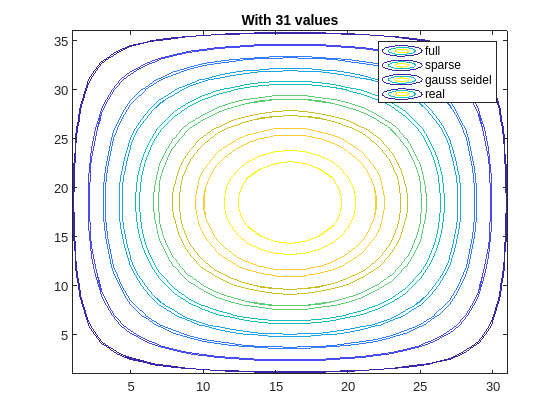

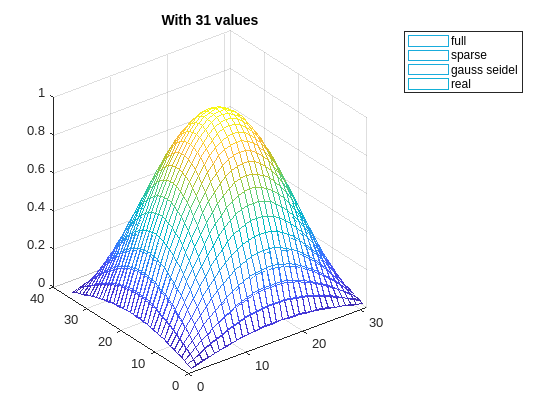

x_full =     0.0022    0.0044    0.0066    0.0088    0.0109    0.0131    0.0152    0.0172    0.0192    0.0212    0.0231    0.0250    0.0268    0.0286    0.0302    0.0318    0.0334    0.0348    0.0362    0.0374    0.0386    0.0397    0.0407    0.0416    0.0424    0.0431    0.0437    0.0441    0.0445    0.0448    0.0450    0.0450    0.0450    0.0448    0.0445    0.0441    0.0437    0.0431    0.0424    0.0416    0.0407    0.0397    0.0386    0.0374    0.0362    0.0348    0.0334    0.0318    0.0302    0.0286
    0.0044    0.0088    0.0132    0.0175    0.0219    0.0261    0.0303    0.0344    0.0385    0.0424    0.0462    0.0500    0.0536    0.0571    0.0604    0.0636    0.0666    0.0695    0.0722    0.0748    0.0771    0.0793    0.0813    0.0831    0.0847    0.0861    0.0872    0.0882    0.0890    0.0895    0.0898    0.0899    0.0898    0.0895    0.0890    0.0882    0.0872    0.0861    0.0847    0.0831    0.0813    0.0793    0.0771    0.0748    0.0722    0.0695    0.0666    0.0636    0.0604

x_sparse =     0.0022    0.0044    0.0066    0.0088    0.0109    0.0131    0.0152    0.0172    0.0192    0.0212    0.0231    0.0250    0.0268    0.0286    0.0302    0.0318    0.0334    0.0348    0.0362    0.0374    0.0386    0.0397    0.0407    0.0416    0.0424    0.0431    0.0437    0.0441    0.0445    0.0448    0.0450    0.0450    0.0450    0.0448    0.0445    0.0441    0.0437    0.0431    0.0424    0.0416    0.0407    0.0397    0.0386    0.0374    0.0362    0.0348    0.0334    0.0318    0.0302    0.0286
    0.0044    0.0088    0.0132    0.0175    0.0219    0.0261    0.0303    0.0344    0.0385    0.0424    0.0462    0.0500    0.0536    0.0571    0.0604    0.0636    0.0666    0.0695    0.0722    0.0748    0.0771    0.0793    0.0813    0.0831    0.0847    0.0861    0.0872    0.0882    0.0890    0.0895    0.0898    0.0899    0.0898    0.0895    0.0890    0.0882    0.0872    0.0861    0.0847    0.0831    0.0813    0.0793    0.0771    0.0748    0.0722    0.0695    0.0666    0.0636    0.06

x_GS =     0.0018    0.0033    0.0056    0.0077    0.0097    0.0116    0.0134    0.0153    0.0171    0.0188    0.0206    0.0222    0.0238    0.0254    0.0269    0.0283    0.0297    0.0309    0.0322    0.0333    0.0344    0.0353    0.0362    0.0370    0.0377    0.0384    0.0389    0.0393    0.0397    0.0399    0.0401    0.0401    0.0401    0.0399    0.0397    0.0394    0.0389    0.0384    0.0378    0.0371    0.0363    0.0354    0.0345    0.0334    0.0323    0.0311    0.0298    0.0284    0.0270    0.0255
    0.0038    0.0076    0.0115    0.0155    0.0193    0.0231    0.0269    0.0306    0.0341    0.0377    0.0411    0.0444    0.0476    0.0507    0.0537    0.0566    0.0593    0.0618    0.0643    0.0665    0.0686    0.0706    0.0724    0.0740    0.0754    0.0766    0.0777    0.0786    0.0793    0.0797    0.0800    0.0802    0.0801    0.0798    0.0793    0.0787    0.0778    0.0768    0.0755    0.0741    0.0725    0.0708    0.0689    0.0668    0.0645    0.0621    0.0595    0.0568    0.0540  

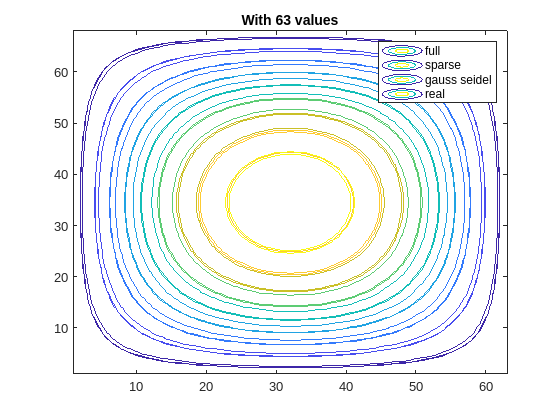

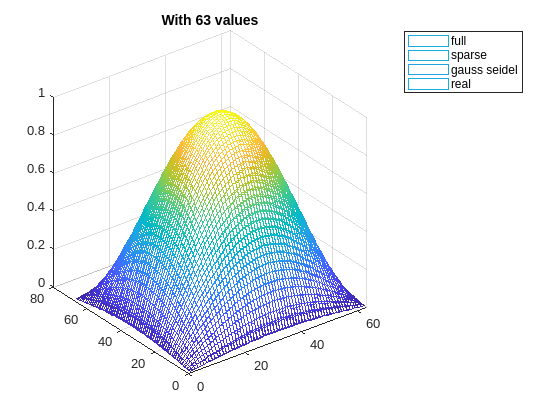

N = [3 7 15 31 63];
f = @(x,y) -2*pi^2*sin(pi*x)*sin(pi*y);
solution_f = @(x,y) sin(pi*x)*sin(pi*y);

for i = 1:length(N)

N_x = N(i)+5;
N_y = N(i);

b = populate_vector(N_x,N_y,f);
 
%% 1
A_full = full_matrix(N_x, N_y);
x_full = reshape(A_full\b, N_x, N_y)

%% 2
A_sparse = sparse_matrix(N_x, N_y);
x_sparse = reshape(A_sparse\b, N_x, N_y)

%% 3
x_GS = gauss_seidel(b,N_x,N_y)

%% analytical solution
x_real = reshape(populate_vector(N_x,N_y, solution_f), N_x, N_y);

err_full(i) = norm(x_real-x_full);
err_sparse(i) = norm(x_real-x_sparse);
err_GS(i) = norm(x_real-x_GS);

figure

contour(x_full);
hold on
contour(x_sparse);
contour(x_GS);
contour(x_real);
hold off

title("With " + N(i) + " values")
legend("full", "sparse", "gauss seidel", "real")

figure

mesh(x_full);
hold on
mesh(x_sparse);
mesh(x_GS);
mesh(x_real);
hold off

title("With " + N(i) + " values")
legend("full", "sparse", "gauss seidel", "real")

end

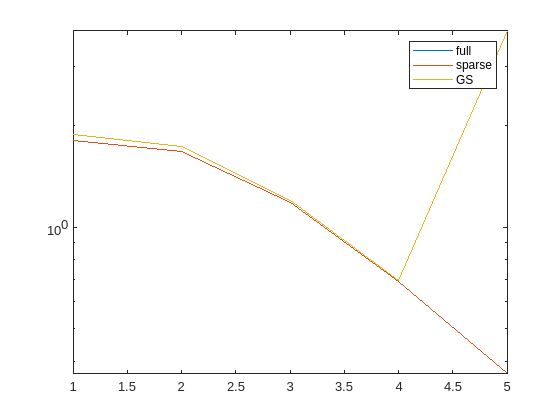

figure
semilogy(err_full)
hold on
semilogy(err_sparse)
semilogy(err_GS)
legend("full", "sparse", "GS")

**f)** Visualize the solutions as a

**1)** a coloured surface where the temperature represents the height of the surface,

**2)** a contour plot.

for $N_x = N_y = 3, 7, 15, 31, 63$. Set the range of the temperature values so that the surface doesn’t look flat. Think about a reasonable range.

**Remark:** Also include the boundary values i.e. your plot should contain $(N_x +2) \cdot (N_y + 2)$ data points.

**g)** Compare the runtimes and the storage requirements (measured by the number of doubles needed to store the matrices and vectors) for 1) – 3) in a) and for $N_x = N_y = 7, 15, 31, 63$:

direct_solution_full_table = table([7 nan nan]', [15 nan nan]', [31 nan nan]',...
    [63 nan nan]','rownames', {'N_x, N_y', 'runtime', 'storage'}, 'VariableNames', ...
    {'7', '15', '31','63'} );
T = table(direct_solution_full_table,'VariableNames',{'direct solution with full matrix'}); % Nested table
disp(T)

      direct solution with full matrix  
                 7     15     31     63 
    ____________________________________

    N_x, N_y      7     15     31     63
    runtime     NaN    NaN    NaN    NaN
    storage     NaN    NaN    NaN    NaN



direct_solution_sparse_table = table([7 nan nan]', [15 nan nan]', [31 nan nan]',...
    [63 nan nan]','rownames', {'N_x, N_y', 'runtime', 'storage'}, 'VariableNames', ...
    {'7', '15', '31','63'} );
T = table(direct_solution_sparse_table,'VariableNames',{'direct solution with sparse matrix'}); % Nested table
disp(T)

     direct solution with sparse matrix 
                 7     15     31     63 
    ____________________________________

    N_x, N_y      7     15     31     63
    runtime     NaN    NaN    NaN    NaN
    storage     NaN    NaN    NaN    NaN



iterative_solution_gs_table = table([7 nan nan]', [15 nan nan]', [31 nan nan]',...
    [63 nan nan]','rownames', {'N_x, N_y', 'runtime', 'storage'}, 'VariableNames', ...
    {'7', '15', '31','63'} );
T = table(iterative_solution_gs_table,'VariableNames',{'iterative solution with Gauss-Seidel'}); % Nested table
disp(T)

    iterative solution with Gauss-Seidel
                 7     15     31     63 
    ____________________________________

    N_x, N_y      7     15     31     63
    runtime     NaN    NaN    NaN    NaN
    storage     NaN    NaN    NaN    NaN



**Remark 1:** Consider in the runtime both the matrix construction (if applicable) and the system solution, as this enables a more fair comparison across all three methods.

**Remark 2:** If your Gauss-Seidel runtime is unexpectedly high then this is a sign of a poorly implemented solver!

**h)** Compute the solutions for $N_x = N_y = 7, 15, 31, 63, 127$ with the Gauss-Seidel solver and fill in the resulting errors


$$e=\sqrt{\frac{1}{N_x \cdot N_y}\sum_{j=1}^{N_y}\sum_{i=1}^{N_x}(T_{i,j}-T(x_i,y_j))^2}$$


in the following tabular:

error_table = table([7 nan nan]', [15 nan nan]', [31 nan nan]',...
    [63 nan nan]', [127 nan nan]','rownames', {'N_x = N_y', 'error', 'error red.'}, 'VariableNames', ...
    {'7', '15', '31','63', '127'} );
disp(error_table)

                   7     15     31     63     127
                  ___    ___    ___    ___    ___

    N_x = N_y       7     15     31     63    127
    error         NaN    NaN    NaN    NaN    NaN
    error red.    NaN    NaN    NaN    NaN    NaN

